# Solución por Newton  Raphson Extendido

clear
syms t Theta_1(t) Theta_2(t) Theta_3(t) R_1(t)
syms r_1 r_1y r_2 r_3 x
syms V_r omega_1 omega_2 omega_3 theta_1 theta_2 theta_3 
syms a_r alpha_1 alpha_2 alpha_3


Vr_2=0.075

Vr_2 = 0.0750

Vr_3=0.17

Vr_3 = 0.1700

Vr_1y=0.045

Vr_1y = 0.0450


Vtheta_2=0

Vtheta_2 = 0

Vomega_2=0

Vomega_2 = 0

Valpha_2=0

Valpha_2 = 0


Fc=sin(Theta_1)*R_1-r_1y;
Fc=simplify(Fc,'Steps',5)

$$Fc(t) = \sin\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)-r_{\mathrm{1y}}$$


fc=subs(Fc,[Theta_1, R_1],[theta_1, r_1]);
SolR_1=solve(fc,r_1);

Fx=-R_1*cos(Theta_1)+r_2*cos(Theta_2)+r_3*cos(Theta_3);
Fx=simplify(Fx,'Steps',5)

$$Fx(t) = r_{2}\,\cos\left(\Theta_{2}\left(t\right)\right)-\cos\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)+r_{3}\,\cos\left(\Theta_{3}\left(t\right)\right)$$


fx=formula(subs(Fx,[Theta_1, Theta_2, Theta_3, R_1],[theta_1, theta_2, theta_3, SolR_1]))

$$fx = r_{2}\,\cos\left(\theta_{2}\right)+r_{3}\,\cos\left(\theta_{3}\right)-\frac{r_{\mathrm{1y}}\,\cos\left(\theta_{1}\right)}{\sin\left(\theta_{1}\right)}$$

fx=simplify(fx,'Steps',5)

$$fx = r_{2}\,\cos\left(\theta_{2}\right)+r_{3}\,\cos\left(\theta_{3}\right)-r_{\mathrm{1y}}\,\cot\left(\theta_{1}\right)$$

SolTheta_1=solve(fx,theta_1);


Fy=R_1*sin(Theta_1)-r_2*sin(Theta_2)-r_3*sin(Theta_3);
Fy=simplify(Fy,'Steps',5)

$$Fy(t) = \sin\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)-r_{3}\,\sin\left(\Theta_{3}\left(t\right)\right)-r_{2}\,\sin\left(\Theta_{2}\left(t\right)\right)$$


fy=formula(subs(Fy,[Theta_1, Theta_2, Theta_3, R_1],[theta_1, theta_2, theta_3, SolR_1]))

$$fy = r_{\mathrm{1y}}-r_{2}\,\sin\left(\theta_{2}\right)-r_{3}\,\sin\left(\theta_{3}\right)$$


SolTheta_3=solve(fy,theta_3);
SolTheta_3=SolTheta_3(1)

$$SolTheta\_3 = \mathrm{asin}\left(\frac{r_{\mathrm{1y}}-r_{2}\,\sin\left(\theta_{2}\right)}{r_{3}}\right)$$


DFcDt=diff(Fc);
DFxDt=diff(Fx);
DFyDt=diff(Fy);

F1=formula(subs(DFxDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]))

$$F1 = \omega_{1}\,r_{1}\,\sin\left(\theta_{1}\right)-V_{r}\,\cos\left(\theta_{1}\right)-\omega_{2}\,r_{2}\,\sin\left(\theta_{2}\right)-\omega_{3}\,r_{3}\,\sin\left(\theta_{3}\right)$$

F2=formula(subs(DFyDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]))

$$F2 = V_{r}\,\sin\left(\theta_{1}\right)+\omega_{1}\,r_{1}\,\cos\left(\theta_{1}\right)-\omega_{2}\,r_{2}\,\cos\left(\theta_{2}\right)-\omega_{3}\,r_{3}\,\cos\left(\theta_{3}\right)$$

F3=formula(subs(DFcDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]))

$$F3 = V_{r}\,\sin\left(\theta_{1}\right)+\omega_{1}\,r_{1}\,\cos\left(\theta_{1}\right)$$



D2FcDt2=diff(DFcDt);
D2FxDt2=diff(DFxDt);
D2FyDt2=diff(DFyDt);

F4=formula(subs(D2FcDt2,[diff(diff(R_1)),diff(diff(Theta_1)),diff(diff(Theta_2)),diff(diff(Theta_3)),diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[a_r,alpha_1,alpha_2,alpha_3,V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]))

$$F4 = -r_{1}\,\sin\left(\theta_{1}\right)\,{\omega_{1}}^{2}+2\,V_{r}\,\cos\left(\theta_{1}\right)\,\omega_{1}+a_{r}\,\sin\left(\theta_{1}\right)+\alpha_{1}\,r_{1}\,\cos\left(\theta_{1}\right)$$

F5=formula(subs(D2FxDt2,[diff(diff(R_1)),diff(diff(Theta_1)),diff(diff(Theta_2)),diff(diff(Theta_3)),diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[a_r,alpha_1,alpha_2,alpha_3,V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]))

$$F5 = r_{1}\,\cos\left(\theta_{1}\right)\,{\omega_{1}}^{2}+2\,V_{r}\,\sin\left(\theta_{1}\right)\,\omega_{1}-r_{2}\,\cos\left(\theta_{2}\right)\,{\omega_{2}}^{2}-r_{3}\,\cos\left(\theta_{3}\right)\,{\omega_{3}}^{2}-a_{r}\,\cos\left(\theta_{1}\right)+\alpha_{1}\,r_{1}\,\sin\left(\theta_{1}\right)-\alpha_{2}\,r_{2}\,\sin\left(\theta_{2}\right)-\alpha_{3}\,r_{3}\,\sin\left(\theta_{3}\right)$$

F6=formula(subs(D2FyDt2,[diff(diff(R_1)),diff(diff(Theta_1)),diff(diff(Theta_2)),diff(diff(Theta_3)),diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[a_r,alpha_1,alpha_2,alpha_3,V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]))

$$F6 = -r_{1}\,\sin\left(\theta_{1}\right)\,{\omega_{1}}^{2}+2\,V_{r}\,\cos\left(\theta_{1}\right)\,\omega_{1}+r_{2}\,\sin\left(\theta_{2}\right)\,{\omega_{2}}^{2}+r_{3}\,\sin\left(\theta_{3}\right)\,{\omega_{3}}^{2}+a_{r}\,\sin\left(\theta_{1}\right)+\alpha_{1}\,r_{1}\,\cos\left(\theta_{1}\right)-\alpha_{2}\,r_{2}\,\cos\left(\theta_{2}\right)-\alpha_{3}\,r_{3}\,\cos\left(\theta_{3}\right)$$




Pi=[-0.0997,-0.4684,2.8737,0,0,0,0,0,0]

Pi =    -0.0997   -0.4684    2.8737         0         0         0         0         0         0


## Posición


fP(r_1,theta_1,theta_3)=[fc;fx;fy];
fP=subs(fP,[theta_2,r_1y,r_2,r_3],[Vtheta_2,Vr_1y,Vr_2,Vr_3]);
fP=simplify(fP,'Steps',5);

valTheta_3=subs(SolTheta_3,[theta_2,r_2,r_3,r_1y],[Vtheta_2,Vr_2,Vr_3,Vr_1y]);
ValTheta_1=subs(SolTheta_1,[theta_2,r_2,r_3,r_1y,theta_3],[Vtheta_2,Vr_2,Vr_3,Vr_1y,valTheta_3]);
valR_1=subs(SolR_1,[r_1y,theta_1],[Vr_1y,ValTheta_1]);

JacP=jacobian(fP, [r_1,theta_1,theta_3]);
JacInvP=JacP^-1;

pP=[Pi(1),Pi(2),Pi(3)]';
ValoresPNR(1,:)=pP';
iteraciones=15;
for i=1:iteraciones
    pP=double(pP-JacInvP(pP(1),pP(2),pP(3))*fP(pP(1),pP(2),pP(3)));
    ValoresPNR(i+1,:)=double(pP)';
    ErrorNR(i,:)=abs(ValoresPNR(i,:)-ValoresPNR(i+1,:));
    NormErrorNR(i)=norm(ErrorNR(i,:));
     if NormErrorNR(i)<0.0005
        break;
    end
end
SolPosNR=double(pP);


## Velocidad

fV(V_r,omega_1,omega_3)=[F1;F2;F3];
fV=subs(fV,[theta_2,r_1y,r_2,r_3,r_1,theta_1,theta_3,omega_2],[Vtheta_2,Vr_1y,Vr_2,Vr_3,SolPosNR(1),SolPosNR(2),SolPosNR(3),Vomega_2]);
fV=simplify(fV,'Steps',5);

JacV=jacobian(fV, [V_r,omega_1,omega_3]);
JacInvV=JacV^-1;

pV=[Pi(4),Pi(5),Pi(6)]';
ValoresVNR(1,:)=pV';

iteraciones=15;
for i=1:iteraciones
    pV=double(pV-JacInvV(pV(1),pV(2),pV(3))*fV(pV(1),pV(2),pV(3)));
    ValoresVNR(i+1,:)=double(pV)';
    ErrorNR(i,:)=abs(ValoresVNR(i,:)-ValoresVNR(i+1,:));
    NormErrorNR(i)=norm(ErrorNR(i,:));
     if NormErrorNR(i)<0.0005
        break;
    end
end

SolVelNR=double(pV);

## Aceleración

fA(a_r,alpha_1,alpha_3)=[F4;F5;F6];
fA=subs(fA,[theta_2,r_1y,r_2,r_3,r_1,theta_1,theta_3,omega_2,V_r,omega_1,omega_3,alpha_2],[Vtheta_2,Vr_1y,Vr_2,Vr_3,SolPosNR(1),SolPosNR(2),SolPosNR(3),Vomega_2,SolVelNR(1),SolVelNR(2),SolVelNR(3),Valpha_2]);
fA=simplify(fA,'Steps',5);
JacA=jacobian(fA, [a_r,alpha_1,alpha_3]);
JacInvA=JacA^-1;

PiA=[Pi(7),Pi(8),Pi(9)]';
ValoresANR(1,:)=PiA';

iteraciones=15;
for i=1:iteraciones
    PiA=double(PiA-JacInvA(PiA(1),PiA(2),PiA(3))*fA(PiA(1),PiA(2),PiA(3)));
    ValoresANR(i+1,:)=double(PiA)';
    ErrorNR(i,:)=abs(ValoresANR(i,:)-ValoresANR(i+1,:));
    NormErrorNR(i)=norm(ErrorNR(i,:));
     if NormErrorNR(i)<0.0005
        break;
    end
end
SolAceNR=double(PiA);

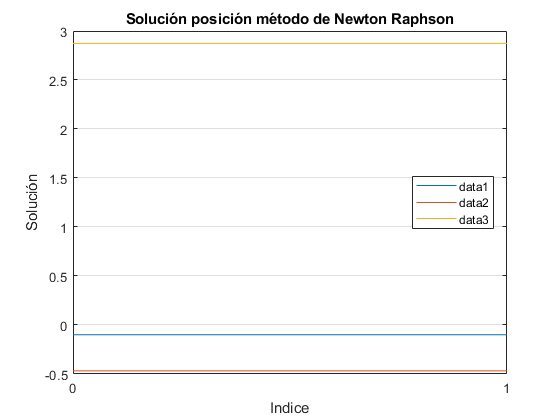

figure()
plot(0:(length(ValoresPNR(:,1))-1),ValoresPNR)
title('Solución posición método de Newton Raphson')
legend('show',"Location","best")
ylabel('Solución')
xlabel('Indice')
xticks(0:length(ValoresPNR))
grid on

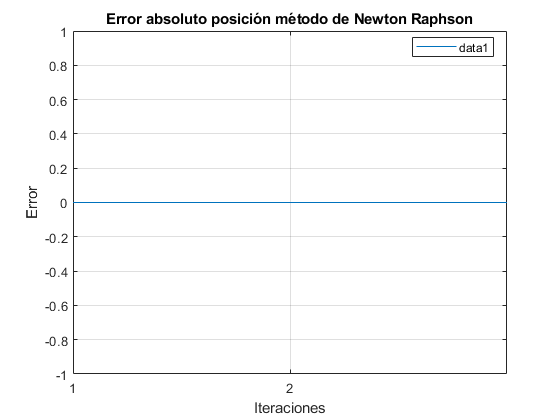

figure()
plot(ErrorNR)
title('Error absoluto posición método de Newton Raphson')
legend('show',"Location","best")
ylabel('Error')
xlabel('Iteraciones')
xticks(1:(length(ValoresPNR)-1))
grid on

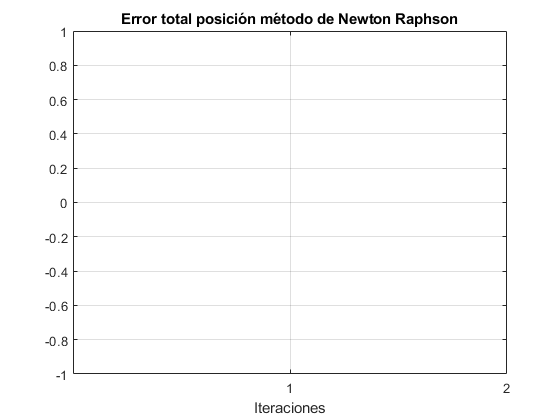

figure()
plot(NormErrorNR)
title('Error total posición método de Newton Raphson')
xlabel('Iteraciones')
xticks(1:(length(ValoresPNR)-1))
grid on

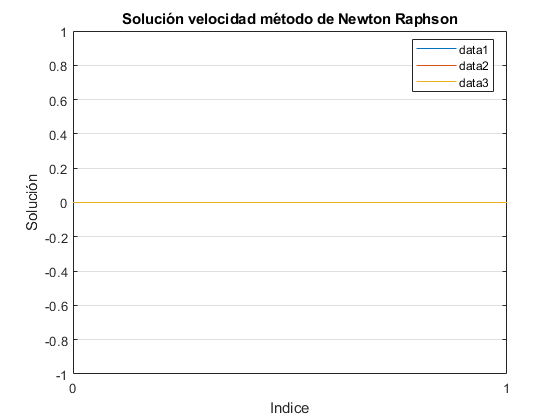



figure()
plot(0:(length(ValoresVNR(:,1))-1),ValoresVNR)
title('Solución velocidad método de Newton Raphson')
legend('show',"Location","best")
ylabel('Solución')
xlabel('Indice')
xticks(0:length(ValoresVNR))
grid on

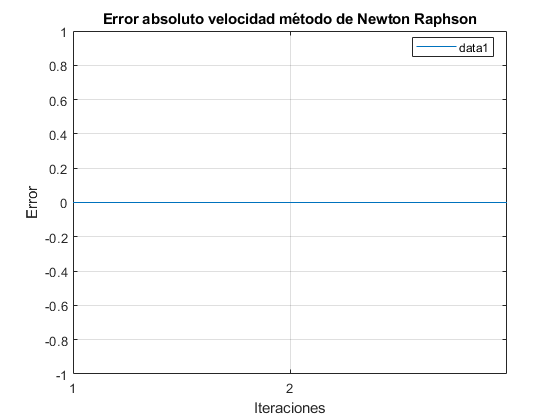

figure()
plot(ErrorNR)
title('Error absoluto velocidad método de Newton Raphson')
legend('show',"Location","best")
ylabel('Error')
xlabel('Iteraciones')
xticks(1:(length(ValoresVNR)-1))
grid on

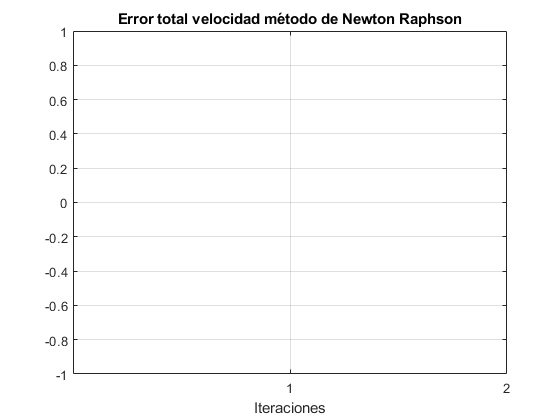

figure()
plot(NormErrorNR)
title('Error total velocidad método de Newton Raphson')
xlabel('Iteraciones')
xticks(1:(length(ValoresVNR)-1))
grid on

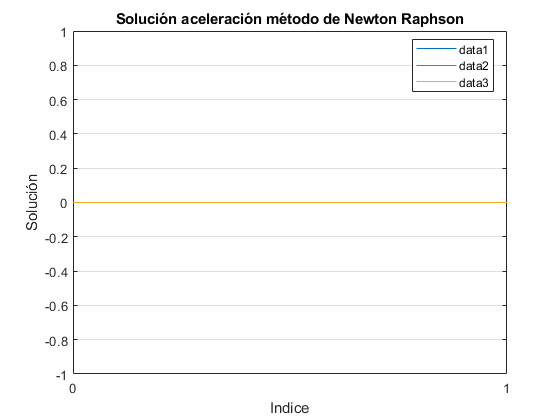


figure()
plot(0:(length(ValoresANR(:,1))-1),ValoresANR)
title('Solución aceleración método de Newton Raphson')
legend('show',"Location","best")
ylabel('Solución')
xlabel('Indice')
xticks(0:length(ValoresANR))
grid on

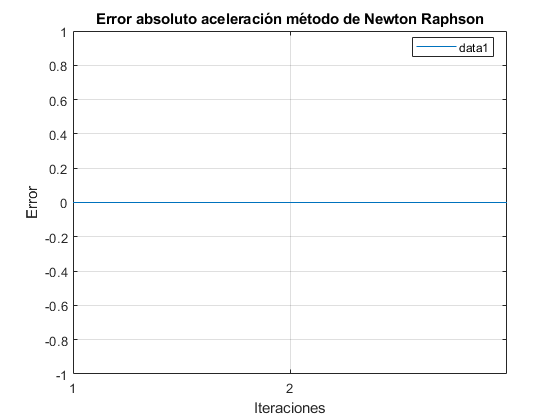

figure()
plot(ErrorNR)
title('Error absoluto aceleración método de Newton Raphson')
legend('show',"Location","best")
ylabel('Error')
xlabel('Iteraciones')
xticks(1:(length(ValoresANR)-1))
grid on

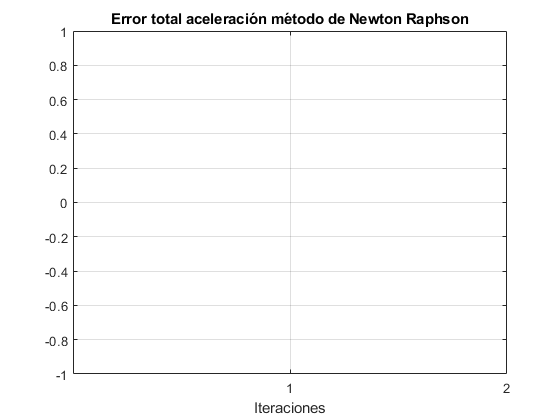

figure()
plot(NormErrorNR)
title('Error total aceleración método de Newton Raphson')
xlabel('Iteraciones')
xticks(1:(length(ValoresANR)-1))
grid on



Solucion=[SolPosNR;SolVelNR;SolAceNR]

Solucion =    -0.0997
   -0.4684
    2.8737
         0
         0
         0
         0
         0
         0
